num = 830;
den = [1 24.93 0];
L1 = tf(num,den)


L1 =
 
       830
  -------------
  s^2 + 24.93 s
 
Continuous-time transfer function.
Model Properties


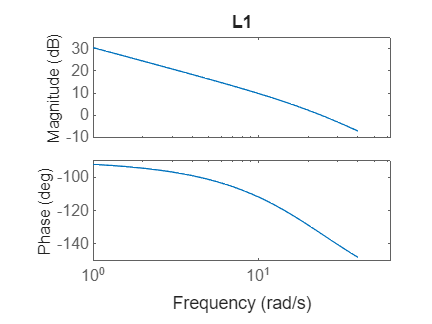

bodeplot(L1,{1,40})
title("L1")


Tau = sqrt(3)/(3*24)

Tau = 0.0241

alpha = 6/40;
C1 = tf([Tau 1],[alpha*Tau 1])


C1 =
 
  0.02406 s + 1
  --------------
  0.003608 s + 1
 
Continuous-time transfer function.
Model Properties


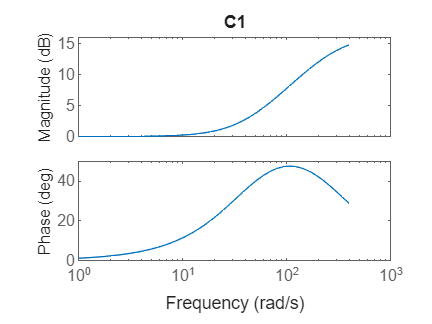

bodeplot(C,{1,400})
title("C1")

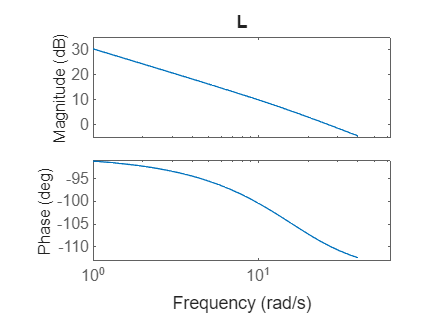




L = L1*C1;
bodeplot(L,{1,40})
title("L")



T = feedback(L1*C1,1,-1)


T =
 
              19.97 s + 830
  --------------------------------------
  0.003608 s^3 + 1.09 s^2 + 44.9 s + 830
 
Continuous-time transfer function.
Model Properties


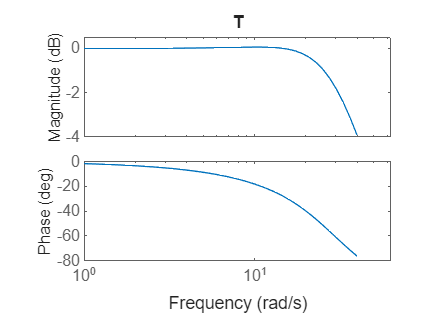

bodeplot(T,{1,40})
title("T")

## Verifcation

C = -23.006 * C1;
plant = tf(-1.4479,[0.0401 1 0])


plant =
 
      -1.448
  --------------
  0.0401 s^2 + s
 
Continuous-time transfer function.
Model Properties



Loop = C*plant;
T_loop = feedback(Loop,1,-1)


T_loop =
 
                0.8013 s + 33.31
  ---------------------------------------------
  0.0001447 s^3 + 0.04371 s^2 + 1.801 s + 33.31
 
Continuous-time transfer function.
Model Properties


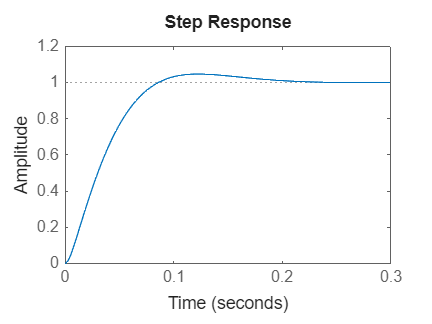


step(T_loop)